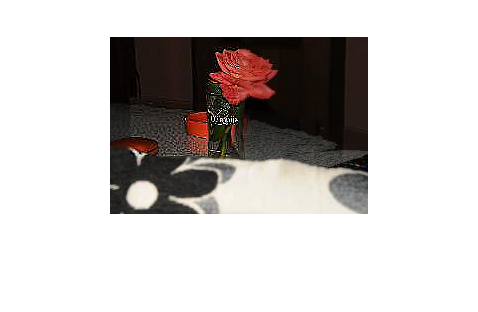

%just change the folder as per your dataset
%change the extension accordingly as well
%make sure line 32 and 33 are uncommented in function block
%this code will run
image_folder = 'test_color_images';
filenames = dir(fullfile(image_folder,'*.jpg'));
total_images = numel(filenames);
%%
maxstd = 0; totstd = [];
xstart = input('enter region of interest for rows  ');
xend = input('enter region of interest ending for rows  ');
ystart = input('enter region of interest for columns  ');
yend = input('enter region of interest for columns for end  ');
%%
for n=1:total_images
    q = fullfile(image_folder,filenames(n).name);
    I = imread(q);
    filter = fspecial('unsharp');
    outimg = RegionofInterest(I,filter,xstart,xend,ystart,yend);
    f = std2(outimg);
    totstd(n) = f;
    if f>maxstd
        maxstd = f;
        consimg = outimg;
    end
end
%%
figure
imshow(consimg) %print the best focused image for ROI chosen

%%to see the mask uncomment 29 and 30 in the function block
%to view the mask evaluate this section of the code in the command line
outimg = RegionofInterest(I,filter,xstart,xend,ystart,yend);